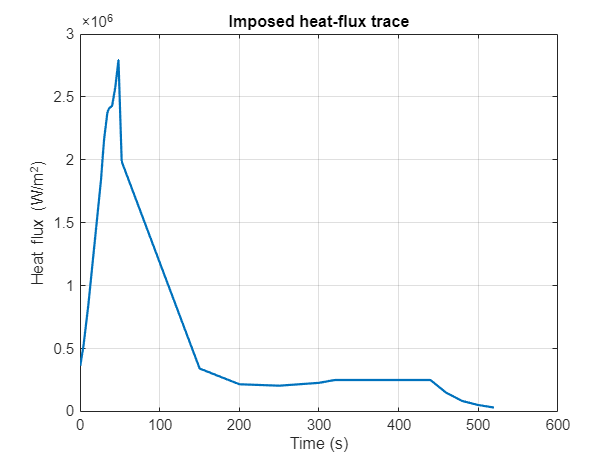

%==========================================================================
% 1D Transient Conduction in a Slab (Crank–Nicolson) with:
%   - Hot face (x = 0): imposed heat flux q_in(t) + convection h_hot (T_s - T_inf)
%                        + radiation εσ (T_s^4 - T_inf^4)
%   - Cold face (x = L): convection h_cold (T_s - T_inf)  [if h_cold = 0 → insulated]
%   - Ablation at the hot face (material removal + ablation heat)
%
% Description:
%   Solves T(x,t) in a 1D slab using a Crank–Nicolson scheme. The hot
%   boundary combines time-varying heat flux, convection, and radiation
%   (the latter linearized each step). An optional ablation model reduces
%   the slab thickness when the hot-surface temperature exceeds T_crit and
%   applies an ablation energy penalty. Thickness changes update the mesh
%   spacing while keeping Nx fixed. The solver is semi-implicit and robust
%   for practical time steps.
%
% User Inputs (edit this block):
%   - Material properties:
%     k       : Thermal conductivity (W/m·K)
%     rho     : Density (kg/m^3)
%     cp      : Specific heat (J/kg·K)
%   - Thickness cases to simulate:
%     L0_values : Vector of initial thicknesses [m] (e.g., [1 5 8 10]/1000)
%   - Discretization and timing:
%     Nx      : Number of spatial nodes (>= 3)
%     dt_max  : Max time step (s)
%     t_max   : Total simulation time (s)
%   - Environment / exchange:
%     T_inf   : Ambient temperature (K)
%     epsilon : Emissivity (hot face)
%     sigmaSB : Stefan–Boltzmann constant (W/m^2·K^4)
%     h_hot   : Convection coefficient at hot face (W/m^2·K)
%     h_cold  : Convection coefficient at cold face (W/m^2·K), 0 → insulated
%   - Ablation model:
%     T_crit        : Hot-face temperature threshold for ablation (K)
%     ablation_rate : Ablation speed (m/s)
%     H_abl         : Ablation specific enthalpy (J/kg)
%     slab_diameter : Circular slab diameter to compute face area (m)
%   - Imposed heat flux:
%      flux_file : File readable by READMATRIX with [t(s), q(W/m^2)]
%      scale_flux: Multiplicative factor applied to read heat flux
%
% Outputs:
%   - Figures: input heat-flux trace, final temperature profiles per case,
%              and cold-face temperature histories.
%   - Console report: final thickness, mass removed, depth removed, and
%                     final cold-face temperature per case.
%==========================================================================

clear; clc; close all;

%% =========================== MATERIAL PROPERTIES ========================
k     = 0.07;             % Thermal conductivity (W/m·K)
rho   = 448;              % Density (kg/m^3)
cp    = 2100;             % Specific heat (J/kg·K)
alpha = k / (rho * cp);   % Thermal diffusivity (m^2/s)

%% ======================== THICKNESSES TO EVALUATE =======================
L0_values = [1, 2, 4, 6, 8, 10] / 1000; % [m]

%% ======================= DISCRETIZATION & TIME ==========================
Nx     = 50;              % Spatial nodes (>= 3)
dt_max = 0.01;            % Max time step (s)
t_max  = 60*5;            % Total simulation time (s)

%% ==================== ENVIRONMENT / HEAT EXCHANGE =======================
T_inf   = 30 + 273.15;    % Ambient temperature (K)
epsilon = 0.8;            % Emissivity (hot face)
sigmaSB = 5.670374419e-8; % Stefan–Boltzmann (W/m^2·K^4)
h_hot   = 120;            % Hot-face convection (W/m^2·K)
h_cold  = 10;             % Cold-face convection (W/m^2·K); 0 → insulated

%% ============================== ABLATION ================================
T_crit        = 1000;         % Ablation threshold (K)
ablation_rate = 1e-6;         % Ablation speed (m/s)
H_abl         = 2.5e6;        % Specific enthalpy of ablation (J/kg)
slab_diameter = 0.400;        % 400 mm (adjust if needed)
slab_area     = pi * (slab_diameter/2)^2;

%% =========================== IMPOSED HEAT FLUX ==========================
flux_file  = 'apollo4_time_flux_real.xlsx';
scale_flux = 1.0;  % e.g., 0.10 for backshell = 10% of frontshell

% Load flux trace [t(s), q(W/m^2)] and build a PCHIP interpolant
[time_values, q_values] = loadHeatflux(flux_file, scale_flux);
q_in = @(t) max(0, interp1(time_values, q_values, t, 'pchip', 0));

% Time resolution constraint from the flux sampling
if numel(time_values) >= 2
    dt_flux = 0.25 * min(diff(time_values));
else
    dt_flux = dt_max;
end

% Plot the input heat flux
figure('Name','Input heat flux','Color','w');
plot(time_values, q_values, 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Heat flux (W/m^2)'); grid on;
title('Imposed heat-flux trace');

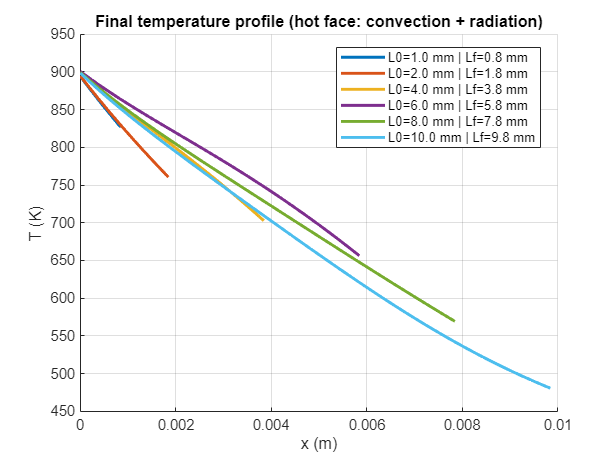

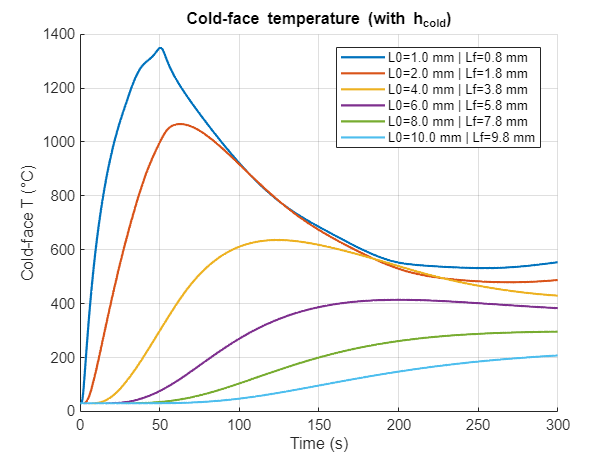


%% ============================ RESULT STRUCT =============================
results = struct('L0',[],'L_final',[],'T_final',[],'t',[],'T_cold',[], ...
                 'mass_loss',[],'depth_loss',[]);
colors = lines(numel(L0_values));

%% ========================== LOOP OVER THICKNESSES =======================
for L_idx = 1:numel(L0_values)

    L  = L0_values(L_idx);
    dx = L / (Nx-1);

    % Time step: consider diffusion, flux resolution, and dt_max
    dt = min([dt_max, dx^2/(4*alpha), dt_flux]);  % CN is unconditionally stable; we still limit dt sensibly
    Nt = max(1, ceil(t_max/dt));
    t  = (0:Nt-1)' * dt;

    % Initial condition
    T = T_inf * ones(Nx,1);

    % Histories
    T_cold     = zeros(Nt,1);
    mass_loss  = 0.0;
    depth_loss = 0.0;

    for n = 1:Nt
        tn = t(n);

        % Crank–Nicolson coefficients
        Fo = alpha * dt / (2 * dx^2);
        A = diag((1 + 2*Fo)*ones(Nx,1)) + diag(-Fo*ones(Nx-1,1), 1) + diag(-Fo*ones(Nx-1,1), -1);
        B = diag((1 - 2*Fo)*ones(Nx,1)) + diag( Fo*ones(Nx-1,1), 1) + diag( Fo*ones(Nx-1,1), -1);

        % ===== Hot face x=0: flux + convection + radiation (linearized) =====
        % Convection (linear term in A): h_hot (T_s - T_inf)
        gamma_conv_hot = (h_hot * dt) / (rho * cp * dx);

        % Radiation linearization around current T(1):
        %   q_rad ≈ εσ (T^4 - T_inf^4)  with  d q_rad / dT ≈ 4 εσ T^3
        gamma_rad_hot  = (4 * epsilon * sigmaSB * T(1)^3 * dt) / (rho * cp * dx);

        % Modify A and B at node 1 (CN with ghost eliminated into coefficients)
        A(1,1) = 1 + 2*Fo + gamma_conv_hot + gamma_rad_hot;
        A(1,2) = -2*Fo;
        B(1,1) = 1 - 2*Fo;
        B(1,2) =  2*Fo;

        % ===== Cold face x=L: convection (h_cold = 0 → insulated) =====
        gamma_conv_cold = (h_cold * dt) / (rho * cp * dx);
        A(end,end)   = 1 + Fo + gamma_conv_cold;
        A(end,end-1) = -Fo;
        B(end,end)   = 1 - Fo;
        B(end,end-1) =  Fo;

        % Right-hand side
        b = B * T;

        % Boundary source terms on b:
        % - Imposed flux at hot face:     + (2 Fo dx / k) q_in(tn)
        % - Hot-face convection constant: + gamma_conv_hot * T_inf
        % - Hot-face radiation explicit:  - [εσ (T^4 - T_inf^4)] * dt / (ρ cp dx)
        % - Cold-face convection const.:  + gamma_conv_cold * T_inf
        b(1)   = b(1) + (2*Fo*dx/k) * q_in(tn) + gamma_conv_hot * T_inf ...
                       - (dt/(rho*cp*dx)) * epsilon * sigmaSB * (T(1)^4 - T_inf^4);
        b(end) = b(end) + gamma_conv_cold * T_inf;

        % Solve linear system
        T_new = A \ b;

        % ------------------------------ ABLATION -----------------------------
        if T_new(1) > T_crit
            dL = ablation_rate * dt;
            dL = min(dL, L - 1e-6);   % do not allow L <= 1e-6
            if dL > 0
                L = L - dL;
                depth_loss = depth_loss + dL;

                % Mass removed and ablation energy applied at the first control volume
                dM    = rho * slab_area * dL;
                mass_loss = mass_loss + dM;

                Q_abl  = dM * H_abl;
                cap_1  = rho * slab_area * dx * cp;  % thermal capacity of the first CV
                dT_abl = Q_abl / cap_1;
                T_new(1) = T_new(1) - dT_abl;

                % Update mesh spacing for the next time step
                dx = L / (Nx-1);
            end
        end

        % Update state and history
        T = T_new;
        T_cold(n) = T(end) - 273.15;  % cold-face temperature in °C
    end

    % Store results for this thickness
    results(L_idx).L0         = L0_values(L_idx);
    results(L_idx).L_final    = L;
    results(L_idx).T_final    = T;
    results(L_idx).t          = t;
    results(L_idx).T_cold     = T_cold;
    results(L_idx).mass_loss  = mass_loss;
    results(L_idx).depth_loss = depth_loss;

    % ---- Plots per thickness ----
    figure(10); if L_idx==1, clf; set(gcf,'Color','w'); hold on; end
    xplot = linspace(0, L, Nx);
    plot(xplot, T, 'LineWidth', 2, 'Color', colors(L_idx,:), ...
        'DisplayName', sprintf('L0=%.1f mm | Lf=%.1f mm', 1e3*results(L_idx).L0, 1e3*L));
    xlabel('x (m)'); ylabel('T (K)'); grid on;
    title('Final temperature profile (hot face: convection + radiation)');
    legend('Location','best');

    figure(20); if L_idx==1, clf; set(gcf,'Color','w'); hold on; end
    plot(t, T_cold, 'LineWidth', 1.5, 'Color', colors(L_idx,:), ...
        'DisplayName', sprintf('L0=%.1f mm | Lf=%.1f mm', 1e3*results(L_idx).L0, 1e3*L));
    xlabel('Time (s)'); ylabel('Cold-face T (°C)'); grid on;
    title('Cold-face temperature (with h_{cold})','Interpreter','tex');
    legend('Location','best');
end

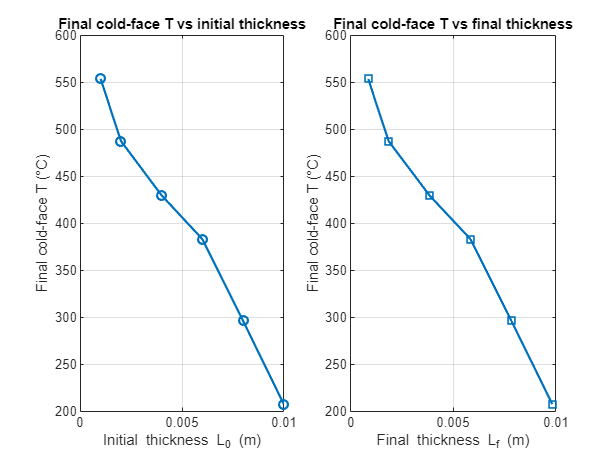


%% ===================== COMPARISON: FINAL T_cold vs L ====================
Lf_all    = [results.L_final]';
L0_all    = [results.L0]';
TendC_all = arrayfun(@(r) r.T_cold(end), results)';

figure('Name','Thickness summary','Color','w');
subplot(1,2,1);
plot(L0_all, TendC_all, '-o', 'LineWidth', 1.5); grid on;
xlabel('Initial thickness L_0 (m)','Interpreter','tex');
ylabel('Final cold-face T (°C)');
title('Final cold-face T vs initial thickness');

subplot(1,2,2);
plot(Lf_all, TendC_all, '-s', 'LineWidth', 1.5); grid on;
xlabel('Final thickness L_f (m)','Interpreter','tex');
ylabel('Final cold-face T (°C)');
title('Final cold-face T vs final thickness');


%% ============================= CONSOLE REPORT ===========================
fprintf('\n======================== SUMMARY ========================\n');


======================== SUMMARY ========================


for i = 1:numel(results)
    fprintf(['Case %d: L0 = %.4f m  |  Lf = %.4f m  |  ΔL = %.2f mm  |  ', ...
             'ablated mass = %.4f kg  |  T_cold,end = %.2f °C\n'], ...
             i, results(i).L0, results(i).L_final, 1e3*results(i).depth_loss, ...
             results(i).mass_loss, results(i).T_cold(end));
end

Case 1: L0 = 0.0010 m  |  Lf = 0.0008 m  |  ΔL = 0.15 mm  |  ablated mass = 0.0086 kg  |  T_cold,end = 553.48 °C
Case 2: L0 = 0.0020 m  |  Lf = 0.0018 m  |  ΔL = 0.16 mm  |  ablated mass = 0.0087 kg  |  T_cold,end = 487.34 °C
Case 3: L0 = 0.0040 m  |  Lf = 0.0038 m  |  ΔL = 0.16 mm  |  ablated mass = 0.0088 kg  |  T_cold,end = 429.59 °C
Case 4: L0 = 0.0060 m  |  Lf = 0.0058 m  |  ΔL = 0.16 mm  |  ablated mass = 0.0087 kg  |  T_cold,end = 383.17 °C
Case 5: L0 = 0.0080 m  |  Lf = 0.0078 m  |  ΔL = 0.15 mm  |  ablated mass = 0.0087 kg  |  T_cold,end = 296.20 °C
Case 6: L0 = 0.0100 m  |  Lf = 0.0098 m  |  ΔL = 0.15 mm  |  ablated mass = 0.0087 kg  |  T_cold,end = 207.63 °C


fprintf('=========================================================\n');